clc;close all;clear 

%RESULTADO TEÓRICO

%Masas
m_1 = 0.08; %kg
m_2 = 0.475; %kg
m_3 = 0.81; %kg
m_4 = 0.82; %kg

%CÁLCULO K_1
%Datos
l_1 = [3.2 3.5 3.6 3.75 3.9 4.4] / 100; %[m]
p_1 = [0 70 150 200 300 500] * 9.81e-3; %[N]

% Regresión lineal
coefficients_1 = polyfit(l_1, p_1, 1); 
k_1 = coefficients_1(1); % [N/m]

%CÁLCULO K_2
%Datos
l_2 = [14 13.9 13.75 13.15 12.7 11.9] / 100; %[m]
p_2 = [0 50 100 200 250 500] * 9.81e-3; %[N]

% Regresión lineal
coefficients_2 = polyfit(l_2, p_2, 1); 
k_2 = -coefficients_2(1); % [N/m]

%Definición de matrices
M=[ m_1 0 0 0 ; 0 m_2 0 0 ; 0 0 m_3 0 ; 0 0 0 m_4 ];
K=[k_2 -k_1 0 0; -k_1 k_1+k_2 -2*k_1 0 ; 0 -2*k_1 3*k_1 -2*k_1 ; 0 0 -2*k_1 3*k_1];

%Cálculo valores (D) y vectores propios (V)
[V, D] = eig(K, M);

frecuencias_naturales = sqrt(diag(D)); % Frecuencias naturales
periodos_modales = 2 * pi ./ frecuencias_naturales; % Periodos modales

disp('Frecuencias naturales (1/s):');

Frecuencias naturales (1/s):


disp(frecuencias_naturales/(2*pi));

   0.0000 + 4.8134i
   4.6859 + 0.0000i
   8.1552 + 0.0000i
  10.7645 + 0.0000i




disp('Periodos modales (s):');

Periodos modales (s):


disp(periodos_modales);

   0.0000 - 0.2078i
   0.2134 + 0.0000i
   0.1226 + 0.0000i
   0.0929 + 0.0000i




disp('Formas modales:');

Formas modales:


disp(V);

    1.5674   -1.3134    1.4335   -2.5027
    1.0515   -0.4424    0.0102    0.8966
    0.5398    0.5385   -0.7240   -0.3592
    0.2269    0.8071    0.7079    0.1241



%RESULTADO EXPERIMENTAL

%Cargar archivos
g21 = load('C:\Users\Cristóbal\Documents\GitHub\Dinamica-de-estructuras\Lab_2\Datos_y_codigo\g21.txt'); %Primer modo
g22 = load('C:\Users\Cristóbal\Documents\GitHub\Dinamica-de-estructuras\Lab_2\Datos_y_codigo\g22.txt'); %Segundo modo
g23 = load('C:\Users\Cristóbal\Documents\GitHub\Dinamica-de-estructuras\Lab_2\Datos_y_codigo\g23.txt'); %Tercer modo

%Constantes sensores
c_gl1 = 1.028; 
c_gl2 = 1.029;
c_gl3 = 0.986; 
c_gl4 = 0.999;
c_f = 1.019; 

%Vectores de tiempo de cada registro
t1 = g21(:,1);
t2 = g22(:,1);
t3 = g23(:,1);

% Respuesta aceleración gl1 [g]
Respuesta_1_gl1 = g21(:,2)./c_gl1;
Respuesta_2_gl1 = g22(:,2)./c_gl1;
Respuesta_3_gl1 = g23(:,2)./c_gl1;

% Respuesta aceleración gl2 [g]
Respuesta_1_gl2 = g21(:,3)./c_gl2;
Respuesta_2_gl2 = g22(:,3)./c_gl2;
Respuesta_3_gl2 = g23(:,3)./c_gl2;

% Respuesta aceleración gl1 [g]
Respuesta_1_gl3 = g21(:,4)./c_gl3;
Respuesta_2_gl3 = g22(:,4)./c_gl3;
Respuesta_3_gl3 = g23(:,4)./c_gl3;

% Respuesta aceleración gl2 [g]
Respuesta_1_gl4 = g21(:,5)./c_gl4;
Respuesta_2_gl4 = g22(:,5)./c_gl4;
Respuesta_3_gl4 = g23(:,5)./c_gl4;

%Respuesta aceleración forzante [g]
Respuesta_1_f = g21(:,6)./c_f;
Respuesta_2_f= g22(:,6)./c_f;
Respuesta_3_f = g23(:,6)./c_f;

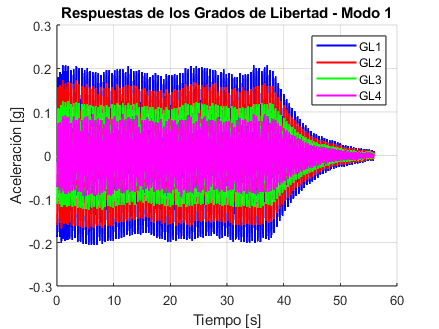

%MODO 1

% Gráfico conjunto de las respuestas del modo 1
figure;
hold on;
plot(t1, Respuesta_1_gl1, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t1, Respuesta_1_gl2, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t1, Respuesta_1_gl3, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t1, Respuesta_1_gl4, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuestas de los Grados de Libertad - Modo 1');
grid on;
legend('show'); 
hold off;

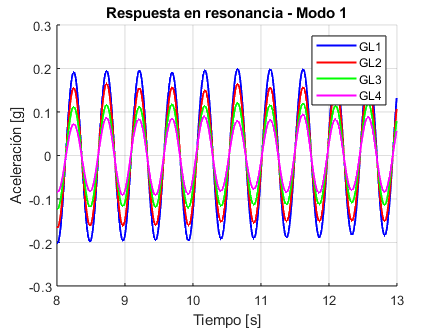


%Detalle de la forma modal modo 1 en resonancia
t1_d = t1(2001:3000);
Respuesta_1_gl1_d = Respuesta_1_gl1(2001:3000);
Respuesta_1_gl2_d = Respuesta_1_gl2(2001:3000);
Respuesta_1_gl3_d = Respuesta_1_gl3(2001:3000);
Respuesta_1_gl4_d = Respuesta_1_gl4(2001:3000);

figure;
hold on;
plot(t1_d, Respuesta_1_gl1_d, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t1_d, Respuesta_1_gl2_d, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t1_d, Respuesta_1_gl3_d, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t1_d, Respuesta_1_gl4_d, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta en resonancia - Modo 1');
grid on;
legend('show'); 
hold off;

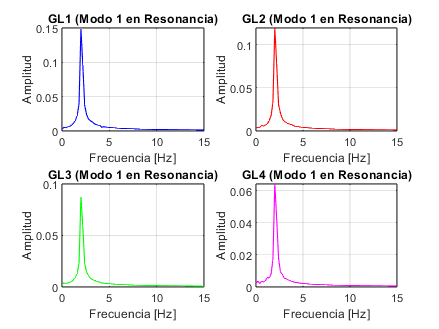


%FOURIER PARA RESPUESTA EN RESONANCIA MODO 1
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_d = length(t1_d);            % Número de muestras en el intervalo
f_d = (0:N_d-1) * (Fs / N_d);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_d = fft(Respuesta_1_gl1_d);
amplitud_GL1_d = abs(FFT_GL1_d) / N_d; 
subplot(2, 2, 1);
plot(f_d(1:N_d/2), 2 * amplitud_GL1_d(1:N_d/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 1 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_d(1:N_d/2));
frecuencias_naturales(1) = f_d(idx);

% FFT para GL2
FFT_GL2_d = fft(Respuesta_1_gl2_d);
amplitud_GL2_d = abs(FFT_GL2_d) / N_d;
subplot(2, 2, 2);
plot(f_d(1:N_d/2), 2 * amplitud_GL2_d(1:N_d/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 1 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_d(1:N_d/2));
frecuencias_naturales(2) = f_d(idx);

% FFT para GL3
FFT_GL3_d = fft(Respuesta_1_gl3_d);
amplitud_GL3_d = abs(FFT_GL3_d) / N_d;
subplot(2, 2, 3);
plot(f_d(1:N_d/2), 2 * amplitud_GL3_d(1:N_d/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 1 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL3_d(1:N_d/2));
frecuencias_naturales(3) = f_d(idx);

% FFT para GL4
FFT_GL4_d = fft(Respuesta_1_gl4_d);
amplitud_GL4_d = abs(FFT_GL4_d) / N_d;
subplot(2, 2, 4);
plot(f_d(1:N_d/2), 2 * amplitud_GL4_d(1:N_d/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 1 en Resonancia)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_d(1:N_d/2));
frecuencias_naturales(4) = f_d(idx);

% Mostrar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 1 (en resonancia):');

Frecuencias naturales modo 1 (en resonancia):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales(i));
end

GL1: 2.000 Hz
GL2: 2.000 Hz
GL3: 2.000 Hz
GL4: 2.000 Hz


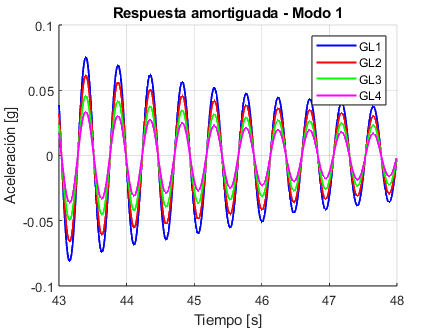


%Detalle de la forma modal modo 1 amortiguado
t1_a = t1(9001:10000);
Respuesta_1_gl1_a = Respuesta_1_gl1(9001:10000);
Respuesta_1_gl2_a = Respuesta_1_gl2(9001:10000);
Respuesta_1_gl3_a = Respuesta_1_gl3(9001:10000);
Respuesta_1_gl4_a = Respuesta_1_gl4(9001:10000);

figure;
hold on;
plot(t1_a, Respuesta_1_gl1_a, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t1_a, Respuesta_1_gl2_a, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t1_a, Respuesta_1_gl3_a, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t1_a, Respuesta_1_gl4_a, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta amortiguada - Modo 1');
grid on;
legend('show'); 
hold off;

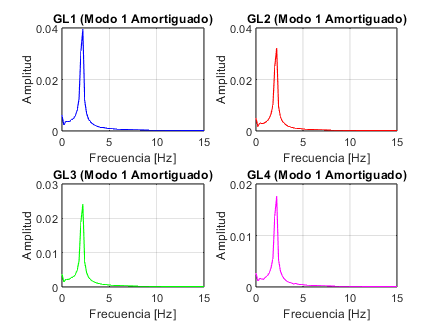


%FOURIER PARA RESPUESTA AMORTIGUADA MODO 1
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_a = length(t1_a);            % Número de muestras en el intervalo
f_a = (0:N_a-1) * (Fs / N_a);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales_amortiguado = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_a = fft(Respuesta_1_gl1_a);
amplitud_GL1_a = abs(FFT_GL1_a) / N_a; 
subplot(2, 2, 1);
plot(f_a(1:N_a/2), 2 * amplitud_GL1_a(1:N_a/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 1 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_a(1:N_a/2));
frecuencias_naturales_amortiguado(1) = f_a(idx);

% FFT para GL2
FFT_GL2_a = fft(Respuesta_1_gl2_a);
amplitud_GL2_a = abs(FFT_GL2_a) / N_a;
subplot(2, 2, 2);
plot(f_a(1:N_a/2), 2 * amplitud_GL2_a(1:N_a/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 1 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_a(1:N_a/2));
frecuencias_naturales_amortiguado(2) = f_a(idx);

% FFT para GL3
FFT_GL3_a = fft(Respuesta_1_gl3_a);
amplitud_GL3_a = abs(FFT_GL3_a) / N_a;
subplot(2, 2, 3);
plot(f_a(1:N_a/2), 2 * amplitud_GL3_a(1:N_a/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 1 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural (máximo pico)
[~, idx] = max(2 * amplitud_GL3_a(1:N_a/2));
frecuencias_naturales_amortiguado(3) = f_a(idx);

% FFT para GL4
FFT_GL4_a = fft(Respuesta_1_gl4_a);
amplitud_GL4_a = abs(FFT_GL4_a) / N_a;
subplot(2, 2, 4);
plot(f_a(1:N_a/2), 2 * amplitud_GL4_a(1:N_a/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 1 Amortiguado)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_a(1:N_a/2));
frecuencias_naturales_amortiguado(4) = f_a(idx);

% Mostar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 1 (Amortiguado):');

Frecuencias naturales modo 1 (Amortiguado):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales_amortiguado(i));
end

GL1: 2.200 Hz
GL2: 2.200 Hz
GL3: 2.200 Hz
GL4: 2.200 Hz



% Calculo de beta para los 4 grados de libertad

% GL1
A_1_abs = abs(Respuesta_1_gl1_a);  
peaks_GL1 = findpeaks(A_1_abs);   
num_maximos1 = 1:length(peaks_GL1); 
regresion1 = polyfit(num_maximos1, log(peaks_GL1), 1); 
beta1 = abs(regresion1(1)) / pi; 

% GL2
A_2_abs = abs(Respuesta_1_gl2_a);
peaks_GL2 = findpeaks(A_2_abs);
num_maximos2 = 1:length(peaks_GL2);
regresion2 = polyfit(num_maximos2, log(peaks_GL2), 1);
beta2 = abs(regresion2(1)) / pi;

% GL3
A_3_abs = abs(Respuesta_1_gl3_a);
peaks_GL3 = findpeaks(A_3_abs);
num_maximos3 = 1:length(peaks_GL3);
regresion3 = polyfit(num_maximos3, log(peaks_GL3), 1);
beta3 = abs(regresion3(1)) / pi;

% GL4
A_4_abs = abs(Respuesta_1_gl4_a);
peaks_GL4 = findpeaks(A_4_abs);
num_maximos4 = 1:length(peaks_GL4);
regresion4 = polyfit(num_maximos4, log(peaks_GL4), 1);
beta4 = abs(regresion4(1)) / pi;

% Mostrar los valores de beta
fprintf('Coeficientes de amortiguamiento modo 1:\n');

Coeficientes de amortiguamiento modo 1:


fprintf('GL1: %.4f\n', beta1);

GL1: 0.0127


fprintf('GL2: %.4f\n', beta2);

GL2: 0.0128


fprintf('GL3: %.4f\n', beta3);

GL3: 0.0125


fprintf('GL4: %.4f\n', beta4);

GL4: 0.0125


fprintf('cuidado');%Remarco cambio entre un modo y otro

cuidado

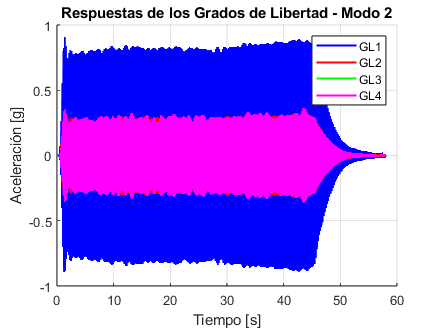

%MODO 2

% Gráfico conjunto de las respuestas del modo 2
figure;
hold on;
plot(t2, Respuesta_2_gl1, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t2, Respuesta_2_gl2, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t2, Respuesta_2_gl3, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t2, Respuesta_2_gl4, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuestas de los Grados de Libertad - Modo 2');
grid on;
legend('show'); 
hold off;

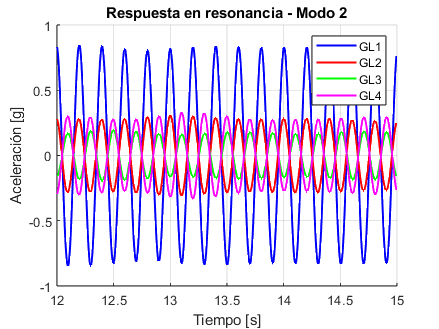


%Detalle de la forma modal modo 2 en resonancia
t2_d = t2(2401:3000);
Respuesta_2_gl1_d = Respuesta_2_gl1(2401:3000);
Respuesta_2_gl2_d = Respuesta_2_gl2(2401:3000);
Respuesta_2_gl3_d = Respuesta_2_gl3(2401:3000);
Respuesta_2_gl4_d = Respuesta_2_gl4(2401:3000);

figure;
hold on;
plot(t2_d, Respuesta_2_gl1_d, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t2_d, Respuesta_2_gl2_d, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t2_d, Respuesta_2_gl3_d, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t2_d, Respuesta_2_gl4_d, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta en resonancia - Modo 2');
grid on;
legend('show'); 
hold off;

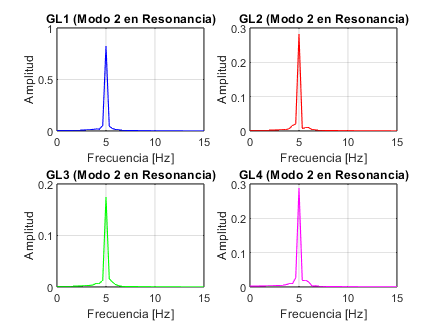


%FOURIER PARA RESPUESTA EN RESONANCIA MODO 2
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_d = length(t2_d);            % Número de muestras en el intervalo
f_d = (0:N_d-1) * (Fs / N_d);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_d = fft(Respuesta_2_gl1_d);
amplitud_GL1_d = abs(FFT_GL1_d) / N_d; 
subplot(2, 2, 1);
plot(f_d(1:N_d/2), 2 * amplitud_GL1_d(1:N_d/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 2 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_d(1:N_d/2));
frecuencias_naturales(1) = f_d(idx);

% FFT para GL2
FFT_GL2_d = fft(Respuesta_2_gl2_d);
amplitud_GL2_d = abs(FFT_GL2_d) / N_d;
subplot(2, 2, 2);
plot(f_d(1:N_d/2), 2 * amplitud_GL2_d(1:N_d/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 2 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_d(1:N_d/2));
frecuencias_naturales(2) = f_d(idx);

% FFT para GL3
FFT_GL3_d = fft(Respuesta_2_gl3_d);
amplitud_GL3_d = abs(FFT_GL3_d) / N_d;
subplot(2, 2, 3);
plot(f_d(1:N_d/2), 2 * amplitud_GL3_d(1:N_d/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 2 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL3_d(1:N_d/2));
frecuencias_naturales(3) = f_d(idx);

% FFT para GL4
FFT_GL4_d = fft(Respuesta_2_gl4_d);
amplitud_GL4_d = abs(FFT_GL4_d) / N_d;
subplot(2, 2, 4);
plot(f_d(1:N_d/2), 2 * amplitud_GL4_d(1:N_d/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 2 en Resonancia)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_d(1:N_d/2));
frecuencias_naturales(4) = f_d(idx);

% Mostrar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 2 (en resonancia):');

Frecuencias naturales modo 2 (en resonancia):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales(i));
end

GL1: 5.000 Hz
GL2: 5.000 Hz
GL3: 5.000 Hz
GL4: 5.000 Hz


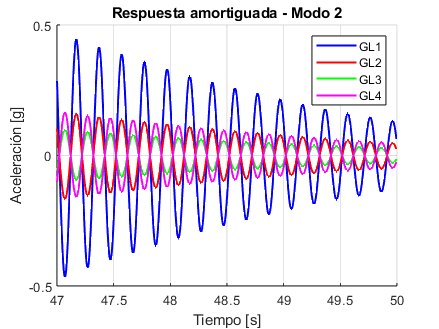


%Detalle de la forma modal modo 2 amortiguado
t2_a = t2(9401:10000);
Respuesta_2_gl1_a = Respuesta_2_gl1(9401:10000);
Respuesta_2_gl2_a = Respuesta_2_gl2(9401:10000);
Respuesta_2_gl3_a = Respuesta_2_gl3(9401:10000);
Respuesta_2_gl4_a = Respuesta_2_gl4(9401:10000);

figure;
hold on;
plot(t2_a, Respuesta_2_gl1_a, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t2_a, Respuesta_2_gl2_a, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t2_a, Respuesta_2_gl3_a, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t2_a, Respuesta_2_gl4_a, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta amortiguada - Modo 2');
grid on;
legend('show'); 
hold off;

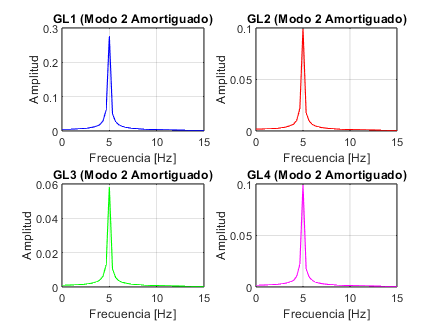


%FOURIER PARA RESPUESTA AMORTIGUADA MODO 2
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_a = length(t2_a);            % Número de muestras en el intervalo
f_a = (0:N_a-1) * (Fs / N_a);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales_amortiguado = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_a = fft(Respuesta_2_gl1_a);
amplitud_GL1_a = abs(FFT_GL1_a) / N_a; 
subplot(2, 2, 1);
plot(f_a(1:N_a/2), 2 * amplitud_GL1_a(1:N_a/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 2 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_a(1:N_a/2));
frecuencias_naturales_amortiguado(1) = f_a(idx);

% FFT para GL2
FFT_GL2_a = fft(Respuesta_2_gl2_a);
amplitud_GL2_a = abs(FFT_GL2_a) / N_a;
subplot(2, 2, 2);
plot(f_a(1:N_a/2), 2 * amplitud_GL2_a(1:N_a/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 2 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_a(1:N_a/2));
frecuencias_naturales_amortiguado(2) = f_a(idx);

% FFT para GL3
FFT_GL3_a = fft(Respuesta_2_gl3_a);
amplitud_GL3_a = abs(FFT_GL3_a) / N_a;
subplot(2, 2, 3);
plot(f_a(1:N_a/2), 2 * amplitud_GL3_a(1:N_a/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 2 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural (máximo pico)
[~, idx] = max(2 * amplitud_GL3_a(1:N_a/2));
frecuencias_naturales_amortiguado(3) = f_a(idx);

% FFT para GL4
FFT_GL4_a = fft(Respuesta_2_gl4_a);
amplitud_GL4_a = abs(FFT_GL4_a) / N_a;
subplot(2, 2, 4);
plot(f_a(1:N_a/2), 2 * amplitud_GL4_a(1:N_a/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 2 Amortiguado)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_a(1:N_a/2));
frecuencias_naturales_amortiguado(4) = f_a(idx);

% Mostar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 2(Amortiguado):');

Frecuencias naturales modo 2(Amortiguado):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales_amortiguado(i));
end

GL1: 5.000 Hz
GL2: 5.000 Hz
GL3: 5.000 Hz
GL4: 5.000 Hz



% Calculo de beta para los 4 grados de libertad

% GL1
A_1_abs = abs(Respuesta_2_gl1_a);  
peaks_GL1 = findpeaks(A_1_abs);   
num_maximos1 = 1:length(peaks_GL1); 
regresion1 = polyfit(num_maximos1, log(peaks_GL1), 1); 
beta1 = abs(regresion1(1)) / pi; 

% GL2
A_2_abs = abs(Respuesta_2_gl2_a);
peaks_GL2 = findpeaks(A_2_abs);
num_maximos2 = 1:length(peaks_GL2);
regresion2 = polyfit(num_maximos2, log(peaks_GL2), 1);
beta2 = abs(regresion2(1)) / pi;

% GL3
A_3_abs = abs(Respuesta_2_gl3_a);
peaks_GL3 = findpeaks(A_3_abs);
num_maximos3 = 1:length(peaks_GL3);
regresion3 = polyfit(num_maximos3, log(peaks_GL3), 1);
beta3 = abs(regresion3(1)) / pi;

% GL4
A_4_abs = abs(Respuesta_2_gl4_a);
peaks_GL4 = findpeaks(A_4_abs);
num_maximos4 = 1:length(peaks_GL4);
regresion4 = polyfit(num_maximos4, log(peaks_GL4), 1);
beta4 = abs(regresion4(1)) / pi;

% Mostrar los valores de beta
fprintf('Coeficientes de amortiguamiento modo 2:\n');

Coeficientes de amortiguamiento modo 2:


fprintf('GL1: %.4f\n', beta1);

GL1: 0.0138


fprintf('GL2: %.4f\n', beta2);

GL2: 0.0136


fprintf('GL3: %.4f\n', beta3);

GL3: 0.0137


fprintf('GL4: %.4f\n', beta4);

GL4: 0.0136


fprintf('cuidado');%Remarco cambio entre un modo y otro

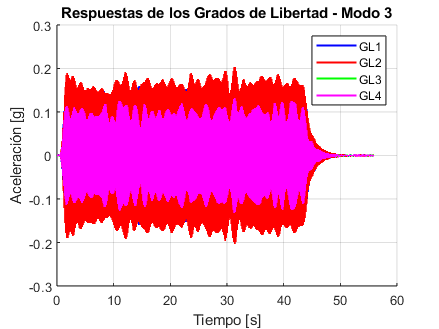

%MODO 3

% Gráfico conjunto de las respuestas del modo 3
figure;
hold on;
plot(t3, Respuesta_3_gl1, 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t3, Respuesta_3_gl2, 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t3, Respuesta_3_gl3, 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t3, Respuesta_3_gl4, 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuestas de los Grados de Libertad - Modo 3');
grid on;
legend('show'); 
hold off;

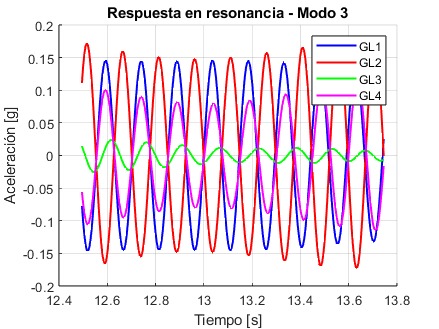


%Detalle de la forma modal modo 3 en resonancia
t3_d = t3(2400:3000);
Respuesta_3_gl1_d = Respuesta_3_gl1(2400:3000);
Respuesta_3_gl2_d = Respuesta_3_gl2(2400:3000);
Respuesta_3_gl3_d = Respuesta_3_gl3(2400:3000);
Respuesta_3_gl4_d = Respuesta_3_gl4(2400:3000);

figure;
hold on;
plot(t3(2500:2750), Respuesta_3_gl1(2500:2750), 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t3(2500:2750), Respuesta_3_gl2(2500:2750), 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t3(2500:2750), Respuesta_3_gl3(2500:2750), 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t3(2500:2750), Respuesta_3_gl4(2500:2750), 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta en resonancia - Modo 3');
grid on;
legend('show'); 
hold off;

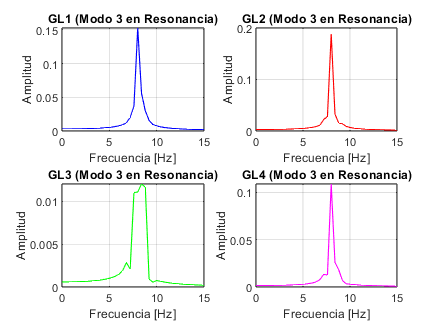


%FOURIER PARA RESPUESTA EN RESONANCIA MODO 3
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_d = length(t2_d);            % Número de muestras en el intervalo
f_d = (0:N_d-1) * (Fs / N_d);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_d = fft(Respuesta_3_gl1_d);
amplitud_GL1_d = abs(FFT_GL1_d) / N_d; 
subplot(2, 2, 1);
plot(f_d(1:N_d/2), 2 * amplitud_GL1_d(1:N_d/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 3 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_d(1:N_d/2));
frecuencias_naturales(1) = f_d(idx);

% FFT para GL2
FFT_GL2_d = fft(Respuesta_3_gl2_d);
amplitud_GL2_d = abs(FFT_GL2_d) / N_d;
subplot(2, 2, 2);
plot(f_d(1:N_d/2), 2 * amplitud_GL2_d(1:N_d/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 3 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_d(1:N_d/2));
frecuencias_naturales(2) = f_d(idx);

% FFT para GL3
FFT_GL3_d = fft(Respuesta_3_gl3_d);
amplitud_GL3_d = abs(FFT_GL3_d) / N_d;
subplot(2, 2, 3);
plot(f_d(1:N_d/2), 2 * amplitud_GL3_d(1:N_d/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 3 en Resonancia)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL3_d(1:N_d/2));
frecuencias_naturales(3) = f_d(idx);

% FFT para GL4
FFT_GL4_d = fft(Respuesta_3_gl4_d);
amplitud_GL4_d = abs(FFT_GL4_d) / N_d;
subplot(2, 2, 4);
plot(f_d(1:N_d/2), 2 * amplitud_GL4_d(1:N_d/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 3 en Resonancia)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_d(1:N_d/2));
frecuencias_naturales(4) = f_d(idx);

% Mostrar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 3 (en resonancia):');

Frecuencias naturales modo 3 (en resonancia):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales(i));
end

GL1: 8.000 Hz
GL2: 8.000 Hz
GL3: 8.400 Hz
GL4: 8.000 Hz


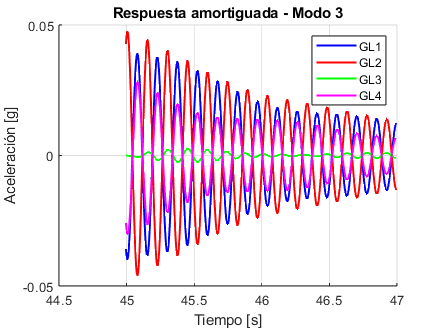


%Detalle de la forma modal modo 3 amortiguado
t3_a = t3(9000:9600);
Respuesta_3_gl1_a = Respuesta_3_gl1(9000:9600);
Respuesta_3_gl2_a = Respuesta_3_gl2(9000:9600);
Respuesta_3_gl3_a = Respuesta_3_gl3(9000:9600);
Respuesta_3_gl4_a = Respuesta_3_gl4(9000:9600);

figure;
hold on;
plot(t3(9000:9400), Respuesta_3_gl1(9000:9400), 'b-', 'LineWidth', 1.5, 'DisplayName', 'GL1');
plot(t3(9000:9400), Respuesta_3_gl2(9000:9400), 'r-', 'LineWidth', 1.5, 'DisplayName', 'GL2');
plot(t3(9000:9400), Respuesta_3_gl3(9000:9400), 'g-', 'LineWidth', 1.5, 'DisplayName', 'GL3');
plot(t3(9000:9400), Respuesta_3_gl4(9000:9400), 'm-', 'LineWidth', 1.5, 'DisplayName', 'GL4');
xlabel('Tiempo [s]');
ylabel('Aceleración [g]');
title('Respuesta amortiguada - Modo 3');
grid on;
legend('show'); 
hold off;

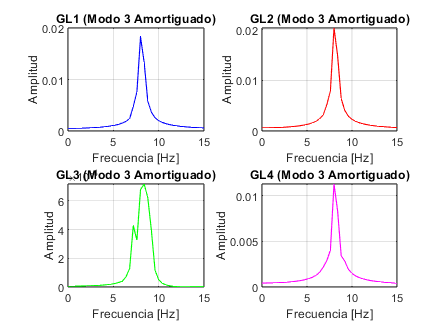


%FOURIER PARA RESPUESTA AMORTIGUADA MODO 3
% Parámetros
Fs = 200;                      % Frecuencia de muestreo [Hz]
N_a = length(t2_a);            % Número de muestras en el intervalo
f_a = (0:N_a-1) * (Fs / N_a);  % Vector de frecuencias

% Prealocar para almacenar frecuencias naturales
frecuencias_naturales_amortiguado = zeros(1, 4);

% Figura con subplots
figure;

% FFT para GL1
FFT_GL1_a = fft(Respuesta_3_gl1_a);
amplitud_GL1_a = abs(FFT_GL1_a) / N_a; 
subplot(2, 2, 1);
plot(f_a(1:N_a/2), 2 * amplitud_GL1_a(1:N_a/2), 'b-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL1 (Modo 3 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural
[~, idx] = max(2 * amplitud_GL1_a(1:N_a/2));
frecuencias_naturales_amortiguado(1) = f_a(idx);

% FFT para GL2
FFT_GL2_a = fft(Respuesta_3_gl2_a);
amplitud_GL2_a = abs(FFT_GL2_a) / N_a;
subplot(2, 2, 2);
plot(f_a(1:N_a/2), 2 * amplitud_GL2_a(1:N_a/2), 'r-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL2 (Modo 3 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL2_a(1:N_a/2));
frecuencias_naturales_amortiguado(2) = f_a(idx);

% FFT para GL3
FFT_GL3_a = fft(Respuesta_3_gl3_a);
amplitud_GL3_a = abs(FFT_GL3_a) / N_a;
subplot(2, 2, 3);
plot(f_a(1:N_a/2), 2 * amplitud_GL3_a(1:N_a/2), 'g-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL3 (Modo 3 Amortiguado)');
grid on;
xlim([0, 15]); 

% Identificar frecuencia natural (máximo pico)
[~, idx] = max(2 * amplitud_GL3_a(1:N_a/2));
frecuencias_naturales_amortiguado(3) = f_a(idx);

% FFT para GL4
FFT_GL4_a = fft(Respuesta_3_gl4_a);
amplitud_GL4_a = abs(FFT_GL4_a) / N_a;
subplot(2, 2, 4);
plot(f_a(1:N_a/2), 2 * amplitud_GL4_a(1:N_a/2), 'm-');
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');
title('GL4 (Modo 3 Amortiguado)');
grid on;
xlim([0, 15]); 


% Identificar frecuencia natural 
[~, idx] = max(2 * amplitud_GL4_a(1:N_a/2));
frecuencias_naturales_amortiguado(4) = f_a(idx);

% Mostar las frecuencias naturales identificadas
disp('Frecuencias naturales modo 3 (Amortiguado):');

Frecuencias naturales modo 3 (Amortiguado):


for i = 1:4
    fprintf('GL%d: %.3f Hz\n', i, frecuencias_naturales_amortiguado(i));
end

GL1: 8.000 Hz
GL2: 8.000 Hz
GL3: 8.400 Hz
GL4: 8.000 Hz



% Calculo de beta para los 4 grados de libertad

% GL1
A_1_abs = abs(Respuesta_3_gl1_a);  
peaks_GL1 = findpeaks(A_1_abs);   
num_maximos1 = 1:length(peaks_GL1); 
regresion1 = polyfit(num_maximos1, log(peaks_GL1), 1); 
beta1 = abs(regresion1(1)) / pi; 

% GL2
A_2_abs = abs(Respuesta_3_gl2_a);
peaks_GL2 = findpeaks(A_2_abs);
num_maximos2 = 1:length(peaks_GL2);
regresion2 = polyfit(num_maximos2, log(peaks_GL2), 1);
beta2 = abs(regresion2(1)) / pi;

% GL3
A_3_abs = abs(Respuesta_3_gl3_a);
peaks_GL3 = findpeaks(A_3_abs);
num_maximos3 = 1:length(peaks_GL3);
regresion3 = polyfit(num_maximos3, log(peaks_GL3), 1);
beta3 = abs(regresion3(1)) / pi;

% GL4
A_4_abs = abs(Respuesta_3_gl4_a);
peaks_GL4 = findpeaks(A_4_abs);
num_maximos4 = 1:length(peaks_GL4);
regresion4 = polyfit(num_maximos4, log(peaks_GL4), 1);
beta4 = abs(regresion4(1)) / pi;

% Mostrar los valores de beta
fprintf('Coeficientes de amortiguamiento modo 3:\n');

Coeficientes de amortiguamiento modo 3:


fprintf('GL1: %.4f\n', beta1);

GL1: 0.0143


fprintf('GL2: %.4f\n', beta2);

GL2: 0.0143


fprintf('GL3: %.4f\n', beta3);

GL3: 0.0129


fprintf('GL4: %.4f\n', beta4);

GL4: 0.0142
